Colored noise visualizer

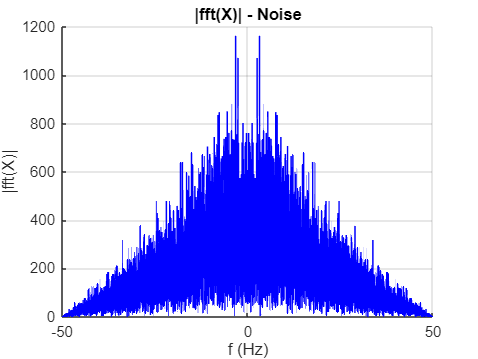

clear, clc
close all

addpath(genpath("./Functions"))

fcut =0.3;
butterOrder =1;

variance = 15;
fs = 100;
t = 0:1/fs:100;
white_noise = sqrt(variance)*randn(size(t));

[b, a] = butter(butterOrder, fcut, 'low');
pink_noise = filter(b, a, white_noise);

[Y_pink,f] = dft(pink_noise,t);
figure, hold on, grid on, title("|fft(X)| - Noise"), xlabel("f (Hz)"), ylabel("|fft(X)|")
plot(f,abs(Y_pink),"LineWidth",1,Color=[0,0,1])